# **Progetto regolatore con luogo delle radici**

#### inizializzazione dell'ambiente

clear
close all
clc

#### Definizione della funzione di trasferimento tempo continuo del processo

% parameters
Tau = 0.07;
T = 0.12;
mu = 1;

% G_ = G not delayed
G_ = tf(mu, [T 1 0]);

% G
G = G_;
G.IODelay = Tau

G =
 
                      1
  exp(-0.07*s) * ------------
                 0.12 s^2 + s
 
Continuous-time transfer function.



**Definizione della funzione di trasferimento tempo discreto del processo**

%discretizzazione di G
Tc = 0.1;
G_d = c2d(G, Tc)

G_d =
 
           0.003456 z^2 + 0.0422 z + 0.01088
  z^(-1) * ---------------------------------
                z^2 - 1.435 z + 0.4346
 
Sample time: 0.1 seconds
Discrete-time transfer function.



G_d = tf([0.003456 0.0422 0.01088], [1 -1.435 0.4346 0], -1) %riscritto in forma canonica

G_d =
 
  0.003456 z^2 + 0.0422 z + 0.01088
  ---------------------------------
     z^3 - 1.435 z^2 + 0.4346 z
 
Sample time: unspecified
Discrete-time transfer function.



**Traccio luogo delle radici di G_d**

% poli e zeri di G_d
[poliG_d, zeriG_d] = pzmap(G_d)

poliG_d =          0
    1.0007
    0.4343


zeriG_d =   -11.9471
   -0.2635


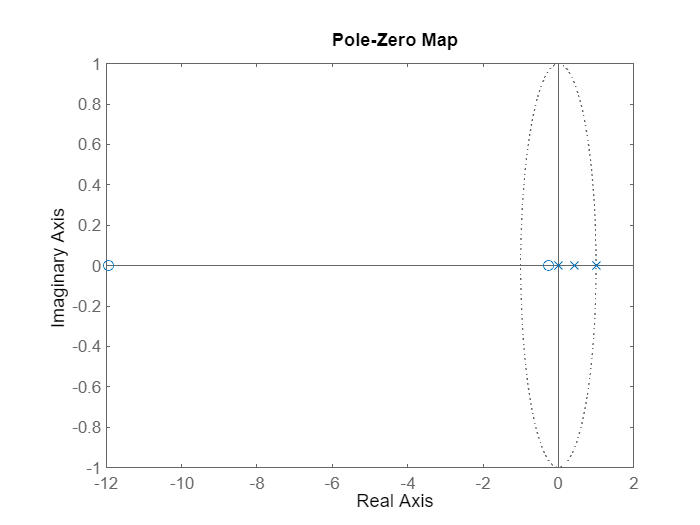

pzmap(G_d)

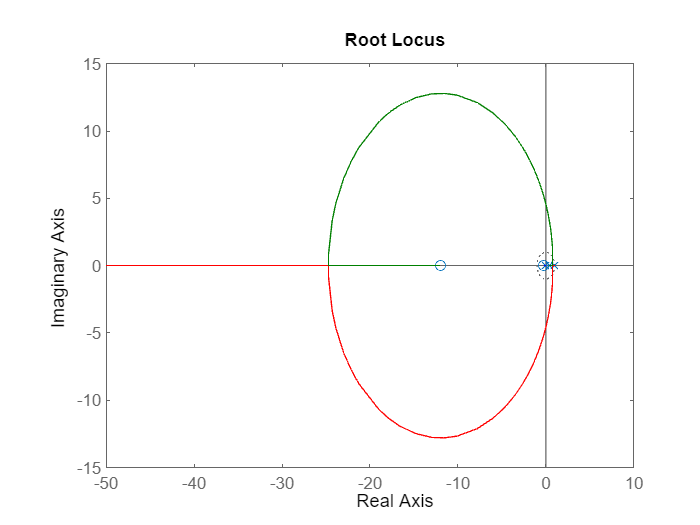


%traccio luogo
rlocus(G_d)

**Opero su luogo delle radici per trovare il regolatore**

% richieste per regolatore:

%  - asintotica stabilità del sistema ad anello chiuso
%  - astatismo a gradino 
%  - tempo assestamento < 0.5s

%rltool(G_d, Tc)
% ho trovato la possibile soluzione

% - zero in 0.4346
% - polo in -0.531

**Dichiaro regolatore senza guadagno**

%R_no_gain = tf([-2.3 1], [1.883 1], Tc)
R_no_gain = tf([1 -0.436], [1 0.531], Tc)

R_no_gain =
 
  z - 0.436
  ---------
  z + 0.531
 
Sample time: 0.1 seconds
Discrete-time transfer function.



**Trovo il guadagno desiderato per le mie specifiche**

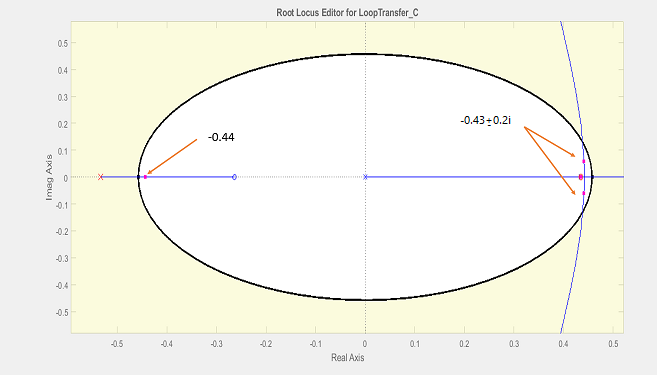

%traccio relazione poli a ciclo chiuso, guadagno d'anello
L_no_gain = G_d* R_no_gain; %open loop senza guadagno

k = (0.1:0.5:20);
r = rlocus(L_no_gain,k)

r =    0.9970 + 0.0000i   0.9782 + 0.0000i   0.9589 + 0.0000i   0.9388 + 0.0000i   0.9181 + 0.0000i   0.8965 + 0.0000i   0.8740 + 0.0000i   0.8503 + 0.0000i   0.8255 + 0.0000i   0.7991 + 0.0000i   0.7708 + 0.0000i   0.7403 + 0.0000i   0.7066 + 0.0000i   0.6688 + 0.0000i   0.6245 + 0.0000i   0.5690 + 0.0000i   0.4953 + 0.0000i   0.4568 + 0.0000i   0.4478 + 0.0000i   0.4443 + 0.0000i   0.4423 + 0.0000i   0.4411 + 0.0000i   0.4403 + 0.0000i   0.4397 + 0.0000i   0.4393 + 0.0000i   0.4389 + 0.0000i   0.4386 + 0.0000i   0.4384 + 0.0000i   0.4382 + 0.0000i   0.4380 + 0.0000i   0.4379 + 0.0000i   0.4378 + 0.0000i   0.4377 + 0.0000i   0.4376 + 0.0000i   0.4375 + 0.0000i   0.4374 + 0.0000i   0.4373 + 0.0000i   0.4373 + 0.0000i   0.4372 + 0.0000i   0.4372 + 0.0000i
  -0.5297 + 0.0000i  -0.5233 + 0.0000i  -0.5169 + 0.0000i  -0.5107 + 0.0000i  -0.5046 + 0.0000i  -0.4986 + 0.0000i  -0.4927 + 0.0000i  -0.4869 + 0.0000i  -0.4813 + 0.0000i  -0.4758 + 0.0000i  -0.4704 + 0.0000i  -0.4652 + 0.0000i  -0.46


%our pole of interest is the last of this column.
display(r(:,19))        %index 19 is the nearest to the desired situation

   0.4478 + 0.0000i
  -0.4322 + 0.0000i
   0.4284 + 0.1987i
   0.4284 - 0.1987i



display(k(19))

    9.1000



%found mu
mu_R = k(19);

**Funzioni definitive**

R = mu_R * R_no_gain        %regolatore

R =
 
  9.1 z - 3.968
  -------------
    z + 0.531
 
Sample time: 0.1 seconds
Discrete-time transfer function.



L = R * G_d                 %open loop function

L =
 
  0.03145 z^3 + 0.3703 z^2 - 0.06842 z - 0.04317
  ----------------------------------------------
     z^4 - 0.904 z^3 - 0.3274 z^2 + 0.2308 z
 
Sample time: 0.1 seconds
Discrete-time transfer function.



L_close = feedback(L, 1)    %close loop function

L_close =
 
    0.03145 z^3 + 0.3703 z^2 - 0.06842 z - 0.04317
  ---------------------------------------------------
  z^4 - 0.8726 z^3 + 0.04292 z^2 + 0.1623 z - 0.04317
 
Sample time: 0.1 seconds
Discrete-time transfer function.



**Qualche test**

%TEST

%poles and zeros 
[poli, zeri] = pzmap(L_close)

poli =   -0.4322 + 0.0000i
   0.4284 + 0.1987i
   0.4284 - 0.1987i
   0.4478 + 0.0000i


zeri =   -11.9471
    0.4360
   -0.2635


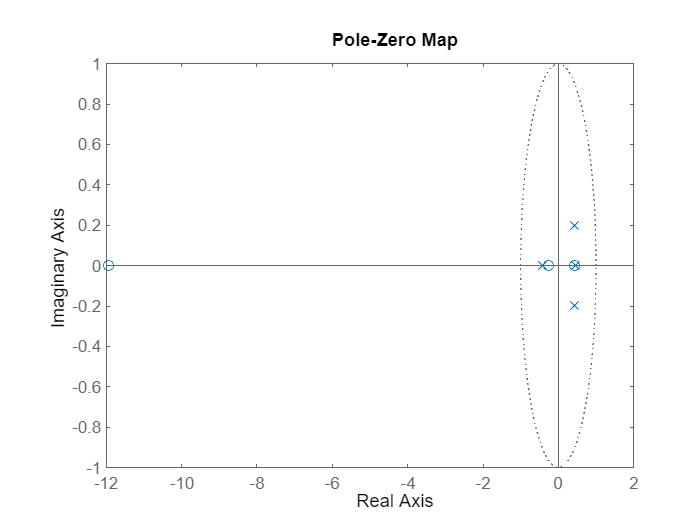

pzmap(L_close)

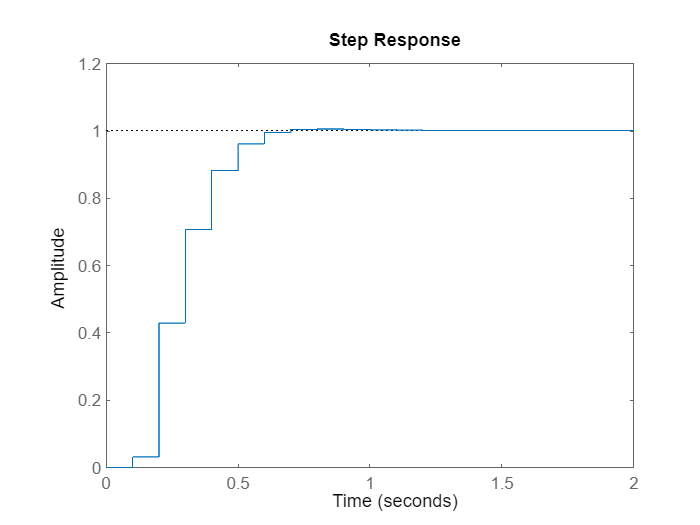



%indicial response
step(L_close)

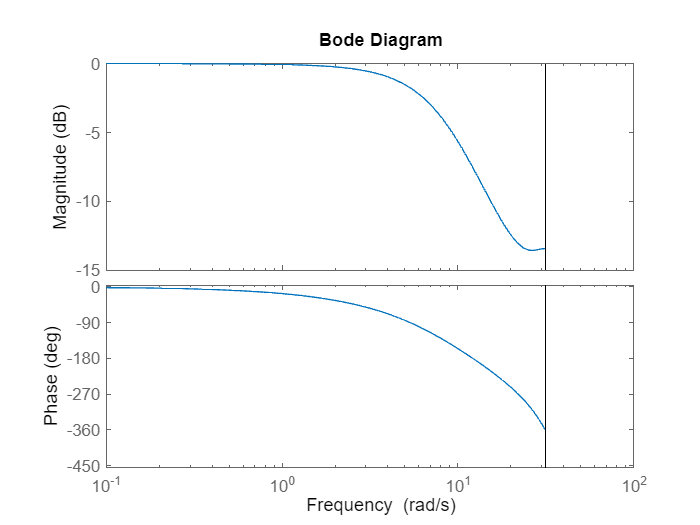



%bode diagram
bode(L_close)

**Analisi risultati:**

**R = (9.1z - 3.968) / (z + 0.531) **

**Garantisce per il nostro sistema a ciclo chiuso:**

- **Stabilità**

- **Tempo di assestamento di circa 0.5s**

- **No sovraelongazione (considerazione su grafico risposta indiciale)**

**Inoltre grazie al polo in 1 di G_d, è garantita la seguente prestazione statica:**

- **astatismo al gradino**